clear 
close all


load('2D\occupancy_map_data4.mat')
map = Map;
load ("2D\occupancy_map4.mat")
Map = occupancyMap(omap);
network = load("2D\DL\mpnet", "mpnet");
mpnet = network.mpnet;

% Define the starting position and orientation of the robot
start_x = 5;
start_y = 8;
start_orientation = 0;

% Define the goal position and orientation for the robot
goal_x = 17;
goal_y = 17;
goal_orientation = 0;

% Combine the start position and orientation into a single pose variable
robot_pose = [start_x, start_y, start_orientation];

% Combine the goal position and orientation into a single pose variable
goal_pose = [goal_x, goal_y, goal_orientation];




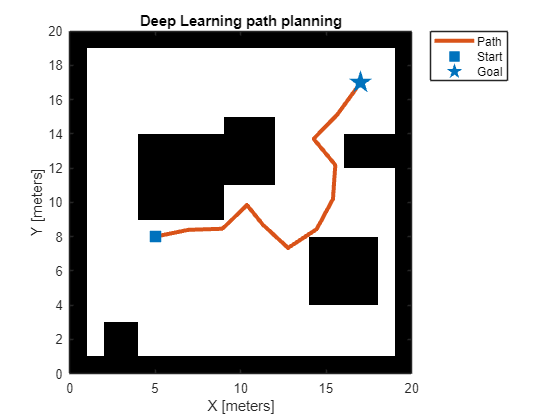

% DL Setup
% We loaded the previously trained deep learning algorithm, and now we are
% going to solve this map

% Create a state space for SE(2) (Special Euclidean group in 2D)
ss = stateSpaceSE2;

% Set the state bounds for the state space
% The bounds are defined as:
%   - x: [0, 20]
%   - y: [0, 20]
%   - theta (orientation): [-pi, pi]
ss.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];

% Create a state sampler using MPNet within the specified state space
stateSamplerDL = stateSamplerMPNET(ss, mpnet);

% Define the start and goal states using the robot's current pose and goal pose
start = robot_pose;
goal = goal_pose;

% Set the environment map for the state sampler
stateSamplerDL.Environment = omap;

% Set the start state for the state sampler
stateSamplerDL.StartState = start;

% Set the goal state for the state sampler
stateSamplerDL.GoalState = goal;

% Create a state validator using the occupancy map
% The validator checks if states are valid (i.e., not in collision)
stateValidator = validatorOccupancyMap(ss, Map=omap);

% Set the validation distance for the state validator
% This is the distance between state samples when validating a path
stateValidator.ValidationDistance = 0.5;

% Create an RRT* planner with the specified state space and state validator
% The planner uses deep learning sampling for state selection
% MaxConnectionDistance specifies the maximum distance between connected states
plannerDLSampling = plannerRRTStar(ss, stateValidator, MaxConnectionDistance=2, StateSampler=stateSamplerDL);

% Plan a path from the start state to the goal state using the RRT* planner
% The path and solution information are returned
[pathDLSampling, solutionInfoDLSampling] = plan(plannerDLSampling, start, goal);

% Visualize results with deep learning based sampling
figure

% Show the occupancy map in the figure
show(omap);

% Hold the current figure to overlay additional plots
hold on;

% Plot the planned path on the map
% The path is plotted using the X and Y coordinates of the states in the path
plot(pathDLSampling.States(:,1), pathDLSampling.States(:,2), plannerLineSpec.path{:})

% Plot the start state on the map
plot(start(1), start(2), plannerLineSpec.start{:})

% Plot the goal state on the map
plot(goal(1), goal(2), plannerLineSpec.goal{:})

% Add a legend to the figure, located outside the northeast of the plot
legend(Location="northeastoutside")

% Add a title to the figure
title("Deep Learning path planning")


% Lidar setup
lidar = rangeSensor;

% VFH (Vector Field Histogram) setup
vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.SafetyDistance = 0.2;
% vfh.DistanceLimits = [1 2]; % Optionally, you can set the distance limits for VFH

% Create figures for visualization
MapFigure = figure;
VFHFigure = figure;

% Modify the map to add obstacles
% Set the cells in the range [10:12, 14:15] to be occupied (value = 1)
map(10:12, 14:15) = 1;

% Flip the map vertically
newMap = flip(map);

% Set the boundaries of the map to be free (value = 0)
newMap(1:end, 1) = 0;  % Left boundary
newMap(1, 1:end) = 0;  % Top boundary
newMap(1:end, end) = 0; % Right boundary
newMap(end, 1:end) = 0; % Bottom boundary

% Create an occupancyMap object from the modified map data

newMap =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     0
     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     0
     0     0     0     

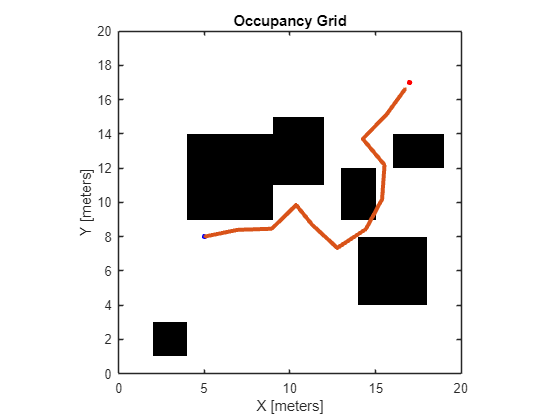

Map = occupancyMap(newMap);

% Display the occupancy map in the MapFigure
figure(MapFigure);
show(Map)

% Hold the current figure to overlay additional plots
hold on

% Plot the robot's starting position on the map with a blue marker
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);

% Plot the goal position on the map with a red marker
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color', "red");

% Plot the planned path on the map using deep learning based sampling
plot(pathDLSampling.States(:,1), pathDLSampling.States(:,2), plannerLineSpec.path{:});


% Initialize an array to store all VFH data (not used in this segment, but may be used later)
allVFHdata = [];


% Create a UAV waypoint follower object
wpFollowerObj = uavWaypointFollower("UAVType", "multirotor", "StartFrom", "first", "Waypoints", pathDLSampling.States);

% Set the transition radius for the UAV waypoint follower
wpFollowerObj.TransitionRadius = 0.5;

% Set the lookahead distance for the UAV waypoint follower
LookAhead = 4;



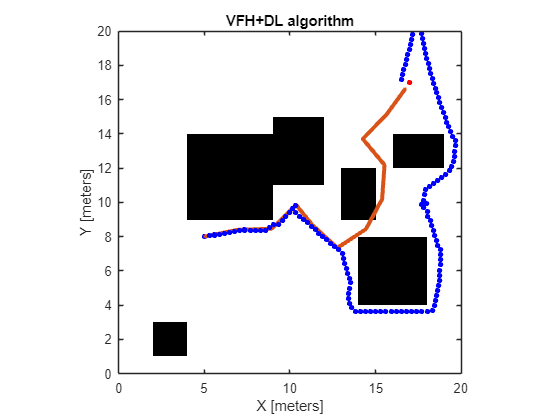

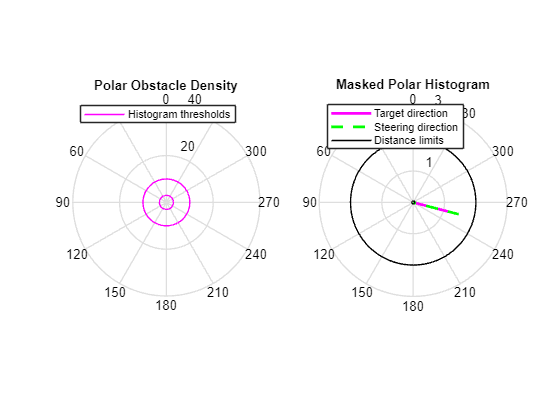

x = 0; % Initialize the variable x
trigger = true; % Set the trigger to true to start the loop

while trigger % Start a while loop that continues as long as the trigger is true
    % Lidar measures
    [ranges, angles] = lidar(robot_pose, Map);
    
    % Geometry about the angles to be appropriate
    % Calculate the Euclidean distance between the robot's current position and the goal position
    tavolsag_goal_x = goal_pose(1) - robot_pose(1);
    tavolsag_goal_y = goal_pose(2) - robot_pose(2);
    
    % Define the robot's pose including its orientation
    Pose = [robot_pose pi/2]';
    
    % Get the lookahead point and other relevant parameters from the UAV waypoint follower
    [lookaheadPoint, desiredCourse, desiredYaw, lookaheadDistFlag, crossTrackError, status] = wpFollowerObj(Pose, LookAhead);
    
    % Extract the x and y components of the lookahead point
    tavolsag_x = lookaheadPoint(1) - robot_pose(1);
    tavolsag_y = lookaheadPoint(2) - robot_pose(2);
    
    % Calculate the angle between the robot's current position and the lookahead point
    goal_angle = atan2d(tavolsag_y, tavolsag_x);
    
    % Correct the angle with the original orientation of the UAV
    goal_angle = deg2rad(goal_angle) + deg2rad(0 - start_orientation);
    
    % Scan the environment using lidar
    scan = lidarScan(ranges, angles);
    
    % Rotate the lidar scan to be according to the drone's orientation
    rotateScan = transformScan(scan, [0, 0, robot_pose(3) + deg2rad(0 - start_orientation)]);
    
    % Use the VFH algorithm to calculate the required steering angle in radians
    steeringDir = vfh(rotateScan, goal_angle);
    
    % Convert the steering angle to degrees
    new_deg = rad2deg(steeringDir);
    
    % Show the VFH output in the VFHFigure
    figure(VFHFigure)
    show(vfh)
    
    % Drone parameter setup
    v_drone = 0.3; % Speed of the drone in m/s (initially set to 0.3, can be adjusted dynamically)
    
    % Update the robot's orientation to the new steering direction
    robot_pose(3) = new_deg;
    
    % Update the robot's position based on the new orientation and speed
    robot_pose(1) = robot_pose(1) + cosd(new_deg) * v_drone;
    robot_pose(2) = robot_pose(2) + sind(new_deg) * v_drone;
    
    % Store the current position of the robot in the array allVFHdata
    allVFHdata = [allVFHdata; robot_pose(1), robot_pose(2)];
    
    % Plot the updated robot position on the map
    figure(MapFigure);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
    title("VFH+DL algorithm")
    drawnow
    
    x = x + 1; % Increment the variable x
    
    % Check if the robot is close enough to the goal position
    if abs(tavolsag_goal_x) < 0.5 && abs(tavolsag_goal_y) < 0.5
        trigger = false; % Set the trigger to false to exit the loop
    end
end % End of the while loop